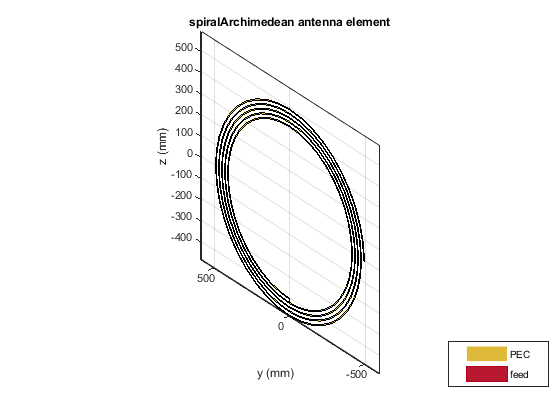

%Item 1 - Criando a antena:
antena_1 = spiralArchimedean('NumArms', 1, 'Turns', 5, 'InnerRadius', .4, 'OuterRadius', .5, 'Tilt', 90, 'TiltAxis', 'Y');
figure
show(antena_1);

% Item 2 - Calculando a impedância:
freq = linspace(1*1e6, 10*1e6, 200);
figure
Z=impedance(antena_1, freq)

Z = 	1.0e+04 *

   0.0000 + 0.0019i   0.0000 + 0.0020i   0.0000 + 0.0021i   0.0000 + 0.0022i   0.0000 + 0.0023i   0.0000 + 0.0024i   0.0000 + 0.0025i   0.0000 + 0.0026i   0.0000 + 0.0027i   0.0000 + 0.0027i   0.0000 + 0.0028i   0.0000 + 0.0029i   0.0000 + 0.0030i   0.0000 + 0.0031i   0.0000 + 0.0032i   0.0000 + 0.0033i   0.0000 + 0.0034i   0.0000 + 0.0035i   0.0000 + 0.0036i   0.0000 + 0.0037i   0.0000 + 0.0038i   0.0000 + 0.0039i   0.0000 + 0.0040i   0.0000 + 0.0041i   0.0000 + 0.0042i   0.0000 + 0.0043i   0.0000 + 0.0044i   0.0000 + 0.0045i   0.0000 + 0.0046i   0.0000 + 0.0047i   0.0000 + 0.0048i   0.0000 + 0.0049i   0.0000 + 0.0050i   0.0000 + 0.0051i   0.0000 + 0.0052i   0.0000 + 0.0053i   0.0000 + 0.0054i   0.0000 + 0.0055i   0.0000 + 0.0056i   0.0000 + 0.0057i   0.0000 + 0.0059i   0.0000 + 0.0060i   0.0000 + 0.0061i   0.0000 + 0.0062i   0.0000 + 0.0063i   0.0000 + 0.0064i   0.0000 + 0.0066i   0.0000 + 0.0067i   0.0000 + 0.0068i   0.0000 + 0.0069i


Zimag=imag(Z)

Zimag = 	1.0e+04 *

    0.0019    0.0020    0.0021    0.0022    0.0023    0.0024    0.0025    0.0026    0.0027    0.0027    0.0028    0.0029    0.0030    0.0031    0.0032    0.0033    0.0034    0.0035    0.0036    0.0037    0.0038    0.0039    0.0040    0.0041    0.0042    0.0043    0.0044    0.0045    0.0046    0.0047    0.0048    0.0049    0.0050    0.0051    0.0052    0.0053    0.0054    0.0055    0.0056    0.0057    0.0059    0.0060    0.0061    0.0062    0.0063    0.0064    0.0066    0.0067    0.0068    0.0069


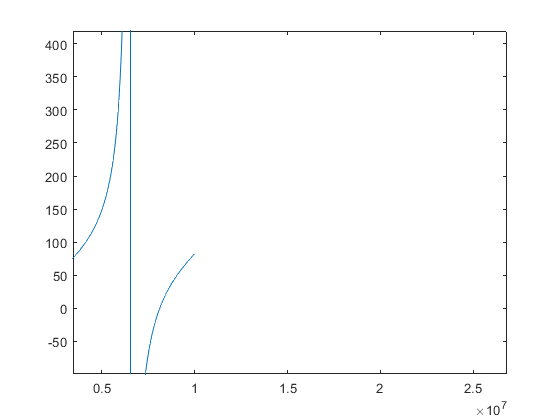

plot(freq,Zimag)
ylim([-100 100])

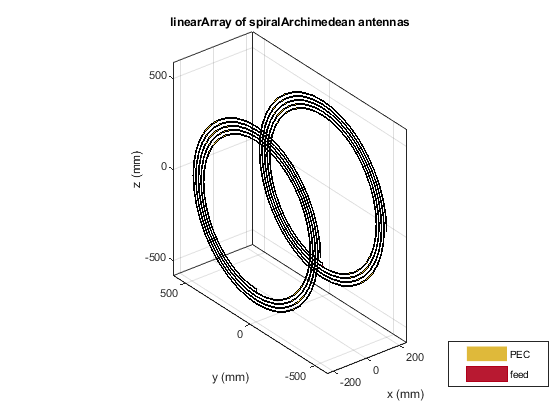


% Item 3 - Antena receptora e array das antenas:
antena_2 = spiralArchimedean('NumArms', 1, 'Turns', 5, 'InnerRadius', .4, 'OuterRadius', .5, 'Tilt', 90, 'TiltAxis', 'Y');
antenas = linearArray('Element', [antena_1 antena_2]);
antenas.ElementSpacing=.4;
figure;
show(antenas);

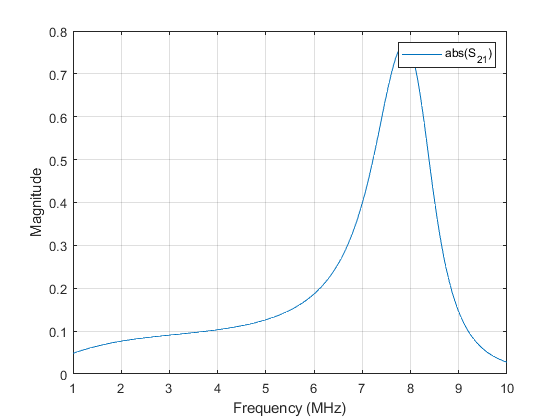

% Item 5 - Simulando Acoplamento e visualizar grafico:
ganhos = sparameters(antenas, freq);
figure;
rfplot(ganhos,2,1,'abs');


% Item 6 - Visualização 3D:

dist=linspace(0.05,0.5,25)

dist =     0.0500    0.0737    0.0974    0.1211    0.1447    0.1684    0.1921    0.2158    0.2395    0.2632    0.2868    0.3105    0.3342    0.3579    0.3816    0.4053    0.4289    0.4526    0.4763    0.5000


ganhos_3d=zeros(length(dist),length(freq))

ganhos_3d =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0 

for i=1:length(dist)
    antenas.ElementSpacing=dist(i)
    ganhos = sparameters(antenas, freq)
    ganhos_3d(i,:) = rfparam(ganhos,2,1);
end

antenas =   linearArray with properties:

           Element: [1×2 spiralArchimedean]
       NumElements: 2
    ElementSpacing: 0.0500
    AmplitudeTaper: 1
        PhaseShift: 0
              Tilt: 0
          TiltAxis: [1 0 0]


ganhos =   sparameters: S-parameters object

       NumPorts: 2
    Frequencies: [200×1 double]
     Parameters: [2×2×200 double]
      Impedance: 50

  rfparam(obj,i,j) returns S-parameter Sij


antenas =   linearArray with properties:

           Element: [1×2 spiralArchimedean]
       NumElements: 2
    ElementSpacing: 0.0737
    AmplitudeTaper: 1
        PhaseShift: 0
              Tilt: 0
          TiltAxis: [1 0 0]


ganhos =   sparameters: S-parameters object

       NumPorts: 2
    Frequencies: [200×1 double]
     Parameters: [2×2×200 double]
      Impedance: 50

  rfparam(obj,i,j) returns S-parameter Sij


antenas =   linearArray with properties:

           Element: [1×2 spiralArchimedean]
       NumElements: 2
    ElementSpacing: 0.0974
    AmplitudeTaper: 1
        PhaseShift: 0
              Tilt: 0
          TiltAxis: [1 0 0]


ganhos =   sparameters: S-parameters object

       NumPorts: 2
    Frequencies: [200×1 double]
     Parameters: [2×2×200 double]
      Impedance: 50

  rfparam(obj,i,j) returns S-parameter Sij


antenas =   linearArray with properties:

           Element: [1×2 spiralArchimedean]
       NumElements: 2
    ElementSpacing: 0.1211
    AmplitudeTaper: 1
        PhaseShift: 0
              Tilt: 0
          TiltAxis: [1 0 0]


ganhos =   sparameters: S-parameters object

       NumPorts: 2
    Frequencies: [200×1 double]
     Parameters: [2×2×200 double]
      Impedance: 50

  rfparam(obj,i,j) returns S-parameter Sij


antenas =   linearArray with properties:

           Element: [1×2 spiralArchimedean]
       NumElements: 2
    ElementSpacing: 0.1447
    AmplitudeTaper: 1
        PhaseShift: 0
              Tilt: 0
          TiltAxis: [1 0 0]


ganhos =   sparameters: S-parameters object

       NumPorts: 2
    Frequencies: [200×1 double]
     Parameters: [2×2×200 double]
      Impedance: 50

  rfparam(obj,i,j) returns S-parameter Sij


antenas =   linearArray with properties:

           Element: [1×2 spiralArchimedean]
       NumElements: 2
    ElementSpacing: 0.1684
    AmplitudeTaper: 1
        PhaseShift: 0
              Tilt: 0
          TiltAxis: [1 0 0]


ganhos =   sparameters: S-parameters object

       NumPorts: 2
    Frequencies: [200×1 double]
     Parameters: [2×2×200 double]
      Impedance: 50

  rfparam(obj,i,j) returns S-parameter Sij


antenas =   linearArray with properties:

           Element: [1×2 spiralArchimedean]
       NumElements: 2
    ElementSpacing: 0.1921
    AmplitudeTaper: 1
        PhaseShift: 0
              Tilt: 0
          TiltAxis: [1 0 0]


ganhos =   sparameters: S-parameters object

       NumPorts: 2
    Frequencies: [200×1 double]
     Parameters: [2×2×200 double]
      Impedance: 50

  rfparam(obj,i,j) returns S-parameter Sij


antenas =   linearArray with properties:

           Element: [1×2 spiralArchimedean]
       NumElements: 2
    ElementSpacing: 0.2158
    AmplitudeTaper: 1
        PhaseShift: 0
              Tilt: 0
          TiltAxis: [1 0 0]


ganhos =   sparameters: S-parameters object

       NumPorts: 2
    Frequencies: [200×1 double]
     Parameters: [2×2×200 double]
      Impedance: 50

  rfparam(obj,i,j) returns S-parameter Sij


antenas =   linearArray with properties:

           Element: [1×2 spiralArchimedean]
       NumElements: 2
    ElementSpacing: 0.2395
    AmplitudeTaper: 1
        PhaseShift: 0
              Tilt: 0
          TiltAxis: [1 0 0]


ganhos =   sparameters: S-parameters object

       NumPorts: 2
    Frequencies: [200×1 double]
     Parameters: [2×2×200 double]
      Impedance: 50

  rfparam(obj,i,j) returns S-parameter Sij


antenas =   linearArray with properties:

           Element: [1×2 spiralArchimedean]
       NumElements: 2
    ElementSpacing: 0.2632
    AmplitudeTaper: 1
        PhaseShift: 0
              Tilt: 0
          TiltAxis: [1 0 0]


ganhos =   sparameters: S-parameters object

       NumPorts: 2
    Frequencies: [200×1 double]
     Parameters: [2×2×200 double]
      Impedance: 50

  rfparam(obj,i,j) returns S-parameter Sij


antenas =   linearArray with properties:

           Element: [1×2 spiralArchimedean]
       NumElements: 2
    ElementSpacing: 0.2868
    AmplitudeTaper: 1
        PhaseShift: 0
              Tilt: 0
          TiltAxis: [1 0 0]


ganhos =   sparameters: S-parameters object

       NumPorts: 2
    Frequencies: [200×1 double]
     Parameters: [2×2×200 double]
      Impedance: 50

  rfparam(obj,i,j) returns S-parameter Sij


antenas =   linearArray with properties:

           Element: [1×2 spiralArchimedean]
       NumElements: 2
    ElementSpacing: 0.3105
    AmplitudeTaper: 1
        PhaseShift: 0
              Tilt: 0
          TiltAxis: [1 0 0]


ganhos =   sparameters: S-parameters object

       NumPorts: 2
    Frequencies: [200×1 double]
     Parameters: [2×2×200 double]
      Impedance: 50

  rfparam(obj,i,j) returns S-parameter Sij


antenas =   linearArray with properties:

           Element: [1×2 spiralArchimedean]
       NumElements: 2
    ElementSpacing: 0.3342
    AmplitudeTaper: 1
        PhaseShift: 0
              Tilt: 0
          TiltAxis: [1 0 0]


ganhos =   sparameters: S-parameters object

       NumPorts: 2
    Frequencies: [200×1 double]
     Parameters: [2×2×200 double]
      Impedance: 50

  rfparam(obj,i,j) returns S-parameter Sij


antenas =   linearArray with properties:

           Element: [1×2 spiralArchimedean]
       NumElements: 2
    ElementSpacing: 0.3579
    AmplitudeTaper: 1
        PhaseShift: 0
              Tilt: 0
          TiltAxis: [1 0 0]


ganhos =   sparameters: S-parameters object

       NumPorts: 2
    Frequencies: [200×1 double]
     Parameters: [2×2×200 double]
      Impedance: 50

  rfparam(obj,i,j) returns S-parameter Sij


antenas =   linearArray with properties:

           Element: [1×2 spiralArchimedean]
       NumElements: 2
    ElementSpacing: 0.3816
    AmplitudeTaper: 1
        PhaseShift: 0
              Tilt: 0
          TiltAxis: [1 0 0]


ganhos =   sparameters: S-parameters object

       NumPorts: 2
    Frequencies: [200×1 double]
     Parameters: [2×2×200 double]
      Impedance: 50

  rfparam(obj,i,j) returns S-parameter Sij


antenas =   linearArray with properties:

           Element: [1×2 spiralArchimedean]
       NumElements: 2
    ElementSpacing: 0.4053
    AmplitudeTaper: 1
        PhaseShift: 0
              Tilt: 0
          TiltAxis: [1 0 0]


ganhos =   sparameters: S-parameters object

       NumPorts: 2
    Frequencies: [200×1 double]
     Parameters: [2×2×200 double]
      Impedance: 50

  rfparam(obj,i,j) returns S-parameter Sij


antenas =   linearArray with properties:

           Element: [1×2 spiralArchimedean]
       NumElements: 2
    ElementSpacing: 0.4289
    AmplitudeTaper: 1
        PhaseShift: 0
              Tilt: 0
          TiltAxis: [1 0 0]


ganhos =   sparameters: S-parameters object

       NumPorts: 2
    Frequencies: [200×1 double]
     Parameters: [2×2×200 double]
      Impedance: 50

  rfparam(obj,i,j) returns S-parameter Sij


antenas =   linearArray with properties:

           Element: [1×2 spiralArchimedean]
       NumElements: 2
    ElementSpacing: 0.4526
    AmplitudeTaper: 1
        PhaseShift: 0
              Tilt: 0
          TiltAxis: [1 0 0]


ganhos =   sparameters: S-parameters object

       NumPorts: 2
    Frequencies: [200×1 double]
     Parameters: [2×2×200 double]
      Impedance: 50

  rfparam(obj,i,j) returns S-parameter Sij


antenas =   linearArray with properties:

           Element: [1×2 spiralArchimedean]
       NumElements: 2
    ElementSpacing: 0.4763
    AmplitudeTaper: 1
        PhaseShift: 0
              Tilt: 0
          TiltAxis: [1 0 0]


ganhos =   sparameters: S-parameters object

       NumPorts: 2
    Frequencies: [200×1 double]
     Parameters: [2×2×200 double]
      Impedance: 50

  rfparam(obj,i,j) returns S-parameter Sij


antenas =   linearArray with properties:

           Element: [1×2 spiralArchimedean]
       NumElements: 2
    ElementSpacing: 0.5000
    AmplitudeTaper: 1
        PhaseShift: 0
              Tilt: 0
          TiltAxis: [1 0 0]


ganhos =   sparameters: S-parameters object

       NumPorts: 2
    Frequencies: [200×1 double]
     Parameters: [2×2×200 double]
      Impedance: 50

  rfparam(obj,i,j) returns S-parameter Sij



figure;
Z=abs(ganhos_3d)

Z =     0.2491    0.2577    0.2660    0.2740    0.2818    0.2893    0.2966    0.3035    0.3103    0.3167    0.3230    0.3289    0.3347    0.3402    0.3455    0.3506    0.3555    0.3601    0.3646    0.3689    0.3730    0.3770    0.3807    0.3843    0.3878    0.3911    0.3942    0.3972    0.4001    0.4029    0.4056    0.4081    0.4105    0.4129    0.4151    0.4173    0.4193    0.4213    0.4232    0.4251    0.4268    0.4285    0.4302    0.4318    0.4334    0.4349    0.4364    0.4378    0.4392    0.4406
    0.2108    0.2182    0.2253    0.2322    0.2389    0.2454    0.2517    0.2577    0.2635    0.2692    0.2746    0.2798    0.2848    0.2896    0.2942    0.2987    0.3030    0.3071    0.3110    0.3148    0.3184    0.3219    0.3252    0.3284    0.3315    0.3344    0.3372    0.3399    0.3425    0.3450    0.3474    0.3497    0.3519    0.3541    0.3561    0.3581    0.3600    0.3618    0.3636    0.3653    0.3670    0.3686    0.3702    0.3717    0.3732    0.3747    0.3761    0.3776    0.3790    0

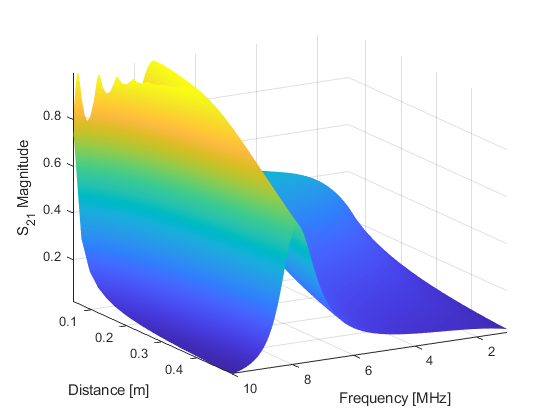

[X,Y]=meshgrid(freq/1e6,dist);
surf(X,Y,Z,'EdgeColor','none');
view(150,20);
shading(gca,'interp');
axis tight;
xlabel('Frequency [MHz]');
ylabel('Distance [m]');
zlabel('S_{21} Magnitude');

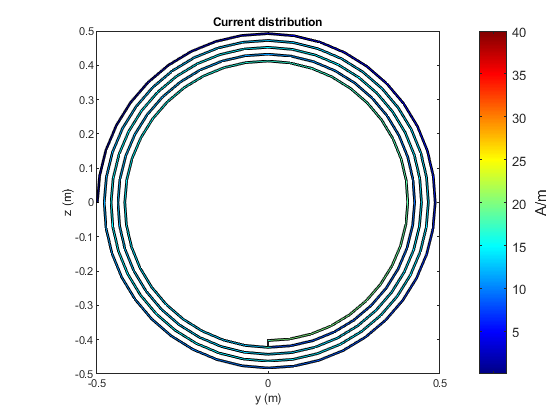

% Item 7 - Corrente:
figure;
current(antena_1,7.9*10^6)

%item9
wr=7.9e6

wr = 7900000

dist=linspace(0.05,0.5,25)

dist =     0.0500    0.0688    0.0875    0.1063    0.1250    0.1437    0.1625    0.1813    0.2000    0.2188    0.2375    0.2563    0.2750    0.2938    0.3125    0.3312    0.3500    0.3688    0.3875    0.4062    0.4250    0.4438    0.4625    0.4812    0.5000


ganhos_3d=zeros

ganhos_3d = 0

for i=1:length(dist)
    antenas.ElementSpacing=dist(i)
    ganho=sparameters(antenas,wr)
    ganhos_3d(i,:) = rfparam(ganho,2,1)
end

antenas =   linearArray with properties:

           Element: [1×2 spiralArchimedean]
       NumElements: 2
    ElementSpacing: 0.0500
    AmplitudeTaper: 1
        PhaseShift: 0
              Tilt: 0
          TiltAxis: [1 0 0]


ganho =   sparameters: S-parameters object

       NumPorts: 2
    Frequencies: 7900000
     Parameters: [2×2 double]
      Impedance: 50

  rfparam(obj,i,j) returns S-parameter Sij


ganhos_3d = -0.8156 - 0.1152i

antenas =   linearArray with properties:

           Element: [1×2 spiralArchimedean]
       NumElements: 2
    ElementSpacing: 0.0688
    AmplitudeTaper: 1
        PhaseShift: 0
              Tilt: 0
          TiltAxis: [1 0 0]


ganho =   sparameters: S-parameters object

       NumPorts: 2
    Frequencies: 7900000
     Parameters: [2×2 double]
      Impedance: 50

  rfparam(obj,i,j) returns S-parameter Sij


ganhos_3d =   -0.8156 - 0.1152i
  -0.8488 - 0.0365i


antenas =   linearArray with properties:

           Element: [1×2 spiralArchimedean]
       NumElements: 2
    ElementSpacing: 0.0875
    AmplitudeTaper: 1
        PhaseShift: 0
              Tilt: 0
          TiltAxis: [1 0 0]


ganho =   sparameters: S-parameters object

       NumPorts: 2
    Frequencies: 7900000
     Parameters: [2×2 double]
      Impedance: 50

  rfparam(obj,i,j) returns S-parameter Sij


ganhos_3d =   -0.8156 - 0.1152i
  -0.8488 - 0.0365i
  -0.8860 + 0.0237i


antenas =   linearArray with properties:

           Element: [1×2 spiralArchimedean]
       NumElements: 2
    ElementSpacing: 0.1063
    AmplitudeTaper: 1
        PhaseShift: 0
              Tilt: 0
          TiltAxis: [1 0 0]


ganho =   sparameters: S-parameters object

       NumPorts: 2
    Frequencies: 7900000
     Parameters: [2×2 double]
      Impedance: 50

  rfparam(obj,i,j) returns S-parameter Sij


ganhos_3d =   -0.8156 - 0.1152i
  -0.8488 - 0.0365i
  -0.8860 + 0.0237i
  -0.9148 + 0.0820i


antenas =   linearArray with properties:

           Element: [1×2 spiralArchimedean]
       NumElements: 2
    ElementSpacing: 0.1250
    AmplitudeTaper: 1
        PhaseShift: 0
              Tilt: 0
          TiltAxis: [1 0 0]


ganho =   sparameters: S-parameters object

       NumPorts: 2
    Frequencies: 7900000
     Parameters: [2×2 double]
      Impedance: 50

  rfparam(obj,i,j) returns S-parameter Sij


ganhos_3d =   -0.8156 - 0.1152i
  -0.8488 - 0.0365i
  -0.8860 + 0.0237i
  -0.9148 + 0.0820i
  -0.9368 + 0.1374i


antenas =   linearArray with properties:

           Element: [1×2 spiralArchimedean]
       NumElements: 2
    ElementSpacing: 0.1437
    AmplitudeTaper: 1
        PhaseShift: 0
              Tilt: 0
          TiltAxis: [1 0 0]


ganho =   sparameters: S-parameters object

       NumPorts: 2
    Frequencies: 7900000
     Parameters: [2×2 double]
      Impedance: 50

  rfparam(obj,i,j) returns S-parameter Sij


ganhos_3d =   -0.8156 - 0.1152i
  -0.8488 - 0.0365i
  -0.8860 + 0.0237i
  -0.9148 + 0.0820i
  -0.9368 + 0.1374i
  -0.9508 + 0.1907i


antenas =   linearArray with properties:

           Element: [1×2 spiralArchimedean]
       NumElements: 2
    ElementSpacing: 0.1625
    AmplitudeTaper: 1
        PhaseShift: 0
              Tilt: 0
          TiltAxis: [1 0 0]


ganho =   sparameters: S-parameters object

       NumPorts: 2
    Frequencies: 7900000
     Parameters: [2×2 double]
      Impedance: 50

  rfparam(obj,i,j) returns S-parameter Sij


ganhos_3d =   -0.8156 - 0.1152i
  -0.8488 - 0.0365i
  -0.8860 + 0.0237i
  -0.9148 + 0.0820i
  -0.9368 + 0.1374i
  -0.9508 + 0.1907i
  -0.9564 + 0.2416i


antenas =   linearArray with properties:

           Element: [1×2 spiralArchimedean]
       NumElements: 2
    ElementSpacing: 0.1813
    AmplitudeTaper: 1
        PhaseShift: 0
              Tilt: 0
          TiltAxis: [1 0 0]


ganho =   sparameters: S-parameters object

       NumPorts: 2
    Frequencies: 7900000
     Parameters: [2×2 double]
      Impedance: 50

  rfparam(obj,i,j) returns S-parameter Sij


ganhos_3d =   -0.8156 - 0.1152i
  -0.8488 - 0.0365i
  -0.8860 + 0.0237i
  -0.9148 + 0.0820i
  -0.9368 + 0.1374i
  -0.9508 + 0.1907i
  -0.9564 + 0.2416i
  -0.9535 + 0.2893i


antenas =   linearArray with properties:

           Element: [1×2 spiralArchimedean]
       NumElements: 2
    ElementSpacing: 0.2000
    AmplitudeTaper: 1
        PhaseShift: 0
              Tilt: 0
          TiltAxis: [1 0 0]


ganho =   sparameters: S-parameters object

       NumPorts: 2
    Frequencies: 7900000
     Parameters: [2×2 double]
      Impedance: 50

  rfparam(obj,i,j) returns S-parameter Sij


ganhos_3d =   -0.8156 - 0.1152i
  -0.8488 - 0.0365i
  -0.8860 + 0.0237i
  -0.9148 + 0.0820i
  -0.9368 + 0.1374i
  -0.9508 + 0.1907i
  -0.9564 + 0.2416i
  -0.9535 + 0.2893i
  -0.9428 + 0.3329i


antenas =   linearArray with properties:

           Element: [1×2 spiralArchimedean]
       NumElements: 2
    ElementSpacing: 0.2188
    AmplitudeTaper: 1
        PhaseShift: 0
              Tilt: 0
          TiltAxis: [1 0 0]


ganho =   sparameters: S-parameters object

       NumPorts: 2
    Frequencies: 7900000
     Parameters: [2×2 double]
      Impedance: 50

  rfparam(obj,i,j) returns S-parameter Sij


ganhos_3d =   -0.8156 - 0.1152i
  -0.8488 - 0.0365i
  -0.8860 + 0.0237i
  -0.9148 + 0.0820i
  -0.9368 + 0.1374i
  -0.9508 + 0.1907i
  -0.9564 + 0.2416i
  -0.9535 + 0.2893i
  -0.9428 + 0.3329i
  -0.9249 + 0.3716i


antenas =   linearArray with properties:

           Element: [1×2 spiralArchimedean]
       NumElements: 2
    ElementSpacing: 0.2375
    AmplitudeTaper: 1
        PhaseShift: 0
              Tilt: 0
          TiltAxis: [1 0 0]


ganho =   sparameters: S-parameters object

       NumPorts: 2
    Frequencies: 7900000
     Parameters: [2×2 double]
      Impedance: 50

  rfparam(obj,i,j) returns S-parameter Sij


ganhos_3d =   -0.8156 - 0.1152i
  -0.8488 - 0.0365i
  -0.8860 + 0.0237i
  -0.9148 + 0.0820i
  -0.9368 + 0.1374i
  -0.9508 + 0.1907i
  -0.9564 + 0.2416i
  -0.9535 + 0.2893i
  -0.9428 + 0.3329i
  -0.9249 + 0.3716i


antenas =   linearArray with properties:

           Element: [1×2 spiralArchimedean]
       NumElements: 2
    ElementSpacing: 0.2563
    AmplitudeTaper: 1
        PhaseShift: 0
              Tilt: 0
          TiltAxis: [1 0 0]


ganho =   sparameters: S-parameters object

       NumPorts: 2
    Frequencies: 7900000
     Parameters: [2×2 double]
      Impedance: 50

  rfparam(obj,i,j) returns S-parameter Sij


ganhos_3d =   -0.8156 - 0.1152i
  -0.8488 - 0.0365i
  -0.8860 + 0.0237i
  -0.9148 + 0.0820i
  -0.9368 + 0.1374i
  -0.9508 + 0.1907i
  -0.9564 + 0.2416i
  -0.9535 + 0.2893i
  -0.9428 + 0.3329i
  -0.9249 + 0.3716i


antenas =   linearArray with properties:

           Element: [1×2 spiralArchimedean]
       NumElements: 2
    ElementSpacing: 0.2750
    AmplitudeTaper: 1
        PhaseShift: 0
              Tilt: 0
          TiltAxis: [1 0 0]


ganho =   sparameters: S-parameters object

       NumPorts: 2
    Frequencies: 7900000
     Parameters: [2×2 double]
      Impedance: 50

  rfparam(obj,i,j) returns S-parameter Sij


ganhos_3d =   -0.8156 - 0.1152i
  -0.8488 - 0.0365i
  -0.8860 + 0.0237i
  -0.9148 + 0.0820i
  -0.9368 + 0.1374i
  -0.9508 + 0.1907i
  -0.9564 + 0.2416i
  -0.9535 + 0.2893i
  -0.9428 + 0.3329i
  -0.9249 + 0.3716i


antenas =   linearArray with properties:

           Element: [1×2 spiralArchimedean]
       NumElements: 2
    ElementSpacing: 0.2938
    AmplitudeTaper: 1
        PhaseShift: 0
              Tilt: 0
          TiltAxis: [1 0 0]


ganho =   sparameters: S-parameters object

       NumPorts: 2
    Frequencies: 7900000
     Parameters: [2×2 double]
      Impedance: 50

  rfparam(obj,i,j) returns S-parameter Sij


ganhos_3d =   -0.8156 - 0.1152i
  -0.8488 - 0.0365i
  -0.8860 + 0.0237i
  -0.9148 + 0.0820i
  -0.9368 + 0.1374i
  -0.9508 + 0.1907i
  -0.9564 + 0.2416i
  -0.9535 + 0.2893i
  -0.9428 + 0.3329i
  -0.9249 + 0.3716i


antenas =   linearArray with properties:

           Element: [1×2 spiralArchimedean]
       NumElements: 2
    ElementSpacing: 0.3125
    AmplitudeTaper: 1
        PhaseShift: 0
              Tilt: 0
          TiltAxis: [1 0 0]


ganho =   sparameters: S-parameters object

       NumPorts: 2
    Frequencies: 7900000
     Parameters: [2×2 double]
      Impedance: 50

  rfparam(obj,i,j) returns S-parameter Sij


ganhos_3d =   -0.8156 - 0.1152i
  -0.8488 - 0.0365i
  -0.8860 + 0.0237i
  -0.9148 + 0.0820i
  -0.9368 + 0.1374i
  -0.9508 + 0.1907i
  -0.9564 + 0.2416i
  -0.9535 + 0.2893i
  -0.9428 + 0.3329i
  -0.9249 + 0.3716i


antenas =   linearArray with properties:

           Element: [1×2 spiralArchimedean]
       NumElements: 2
    ElementSpacing: 0.3312
    AmplitudeTaper: 1
        PhaseShift: 0
              Tilt: 0
          TiltAxis: [1 0 0]


ganho =   sparameters: S-parameters object

       NumPorts: 2
    Frequencies: 7900000
     Parameters: [2×2 double]
      Impedance: 50

  rfparam(obj,i,j) returns S-parameter Sij


ganhos_3d =   -0.8156 - 0.1152i
  -0.8488 - 0.0365i
  -0.8860 + 0.0237i
  -0.9148 + 0.0820i
  -0.9368 + 0.1374i
  -0.9508 + 0.1907i
  -0.9564 + 0.2416i
  -0.9535 + 0.2893i
  -0.9428 + 0.3329i
  -0.9249 + 0.3716i


antenas =   linearArray with properties:

           Element: [1×2 spiralArchimedean]
       NumElements: 2
    ElementSpacing: 0.3500
    AmplitudeTaper: 1
        PhaseShift: 0
              Tilt: 0
          TiltAxis: [1 0 0]


ganho =   sparameters: S-parameters object

       NumPorts: 2
    Frequencies: 7900000
     Parameters: [2×2 double]
      Impedance: 50

  rfparam(obj,i,j) returns S-parameter Sij


ganhos_3d =   -0.8156 - 0.1152i
  -0.8488 - 0.0365i
  -0.8860 + 0.0237i
  -0.9148 + 0.0820i
  -0.9368 + 0.1374i
  -0.9508 + 0.1907i
  -0.9564 + 0.2416i
  -0.9535 + 0.2893i
  -0.9428 + 0.3329i
  -0.9249 + 0.3716i


antenas =   linearArray with properties:

           Element: [1×2 spiralArchimedean]
       NumElements: 2
    ElementSpacing: 0.3688
    AmplitudeTaper: 1
        PhaseShift: 0
              Tilt: 0
          TiltAxis: [1 0 0]


ganho =   sparameters: S-parameters object

       NumPorts: 2
    Frequencies: 7900000
     Parameters: [2×2 double]
      Impedance: 50

  rfparam(obj,i,j) returns S-parameter Sij


ganhos_3d =   -0.8156 - 0.1152i
  -0.8488 - 0.0365i
  -0.8860 + 0.0237i
  -0.9148 + 0.0820i
  -0.9368 + 0.1374i
  -0.9508 + 0.1907i
  -0.9564 + 0.2416i
  -0.9535 + 0.2893i
  -0.9428 + 0.3329i
  -0.9249 + 0.3716i


antenas =   linearArray with properties:

           Element: [1×2 spiralArchimedean]
       NumElements: 2
    ElementSpacing: 0.3875
    AmplitudeTaper: 1
        PhaseShift: 0
              Tilt: 0
          TiltAxis: [1 0 0]


ganho =   sparameters: S-parameters object

       NumPorts: 2
    Frequencies: 7900000
     Parameters: [2×2 double]
      Impedance: 50

  rfparam(obj,i,j) returns S-parameter Sij


ganhos_3d =   -0.8156 - 0.1152i
  -0.8488 - 0.0365i
  -0.8860 + 0.0237i
  -0.9148 + 0.0820i
  -0.9368 + 0.1374i
  -0.9508 + 0.1907i
  -0.9564 + 0.2416i
  -0.9535 + 0.2893i
  -0.9428 + 0.3329i
  -0.9249 + 0.3716i


antenas =   linearArray with properties:

           Element: [1×2 spiralArchimedean]
       NumElements: 2
    ElementSpacing: 0.4062
    AmplitudeTaper: 1
        PhaseShift: 0
              Tilt: 0
          TiltAxis: [1 0 0]


ganho =   sparameters: S-parameters object

       NumPorts: 2
    Frequencies: 7900000
     Parameters: [2×2 double]
      Impedance: 50

  rfparam(obj,i,j) returns S-parameter Sij


ganhos_3d =   -0.8156 - 0.1152i
  -0.8488 - 0.0365i
  -0.8860 + 0.0237i
  -0.9148 + 0.0820i
  -0.9368 + 0.1374i
  -0.9508 + 0.1907i
  -0.9564 + 0.2416i
  -0.9535 + 0.2893i
  -0.9428 + 0.3329i
  -0.9249 + 0.3716i


antenas =   linearArray with properties:

           Element: [1×2 spiralArchimedean]
       NumElements: 2
    ElementSpacing: 0.4250
    AmplitudeTaper: 1
        PhaseShift: 0
              Tilt: 0
          TiltAxis: [1 0 0]


ganho =   sparameters: S-parameters object

       NumPorts: 2
    Frequencies: 7900000
     Parameters: [2×2 double]
      Impedance: 50

  rfparam(obj,i,j) returns S-parameter Sij


ganhos_3d =   -0.8156 - 0.1152i
  -0.8488 - 0.0365i
  -0.8860 + 0.0237i
  -0.9148 + 0.0820i
  -0.9368 + 0.1374i
  -0.9508 + 0.1907i
  -0.9564 + 0.2416i
  -0.9535 + 0.2893i
  -0.9428 + 0.3329i
  -0.9249 + 0.3716i


antenas =   linearArray with properties:

           Element: [1×2 spiralArchimedean]
       NumElements: 2
    ElementSpacing: 0.4438
    AmplitudeTaper: 1
        PhaseShift: 0
              Tilt: 0
          TiltAxis: [1 0 0]


ganho =   sparameters: S-parameters object

       NumPorts: 2
    Frequencies: 7900000
     Parameters: [2×2 double]
      Impedance: 50

  rfparam(obj,i,j) returns S-parameter Sij


ganhos_3d =   -0.8156 - 0.1152i
  -0.8488 - 0.0365i
  -0.8860 + 0.0237i
  -0.9148 + 0.0820i
  -0.9368 + 0.1374i
  -0.9508 + 0.1907i
  -0.9564 + 0.2416i
  -0.9535 + 0.2893i
  -0.9428 + 0.3329i
  -0.9249 + 0.3716i


antenas =   linearArray with properties:

           Element: [1×2 spiralArchimedean]
       NumElements: 2
    ElementSpacing: 0.4625
    AmplitudeTaper: 1
        PhaseShift: 0
              Tilt: 0
          TiltAxis: [1 0 0]


ganho =   sparameters: S-parameters object

       NumPorts: 2
    Frequencies: 7900000
     Parameters: [2×2 double]
      Impedance: 50

  rfparam(obj,i,j) returns S-parameter Sij


ganhos_3d =   -0.8156 - 0.1152i
  -0.8488 - 0.0365i
  -0.8860 + 0.0237i
  -0.9148 + 0.0820i
  -0.9368 + 0.1374i
  -0.9508 + 0.1907i
  -0.9564 + 0.2416i
  -0.9535 + 0.2893i
  -0.9428 + 0.3329i
  -0.9249 + 0.3716i


antenas =   linearArray with properties:

           Element: [1×2 spiralArchimedean]
       NumElements: 2
    ElementSpacing: 0.4812
    AmplitudeTaper: 1
        PhaseShift: 0
              Tilt: 0
          TiltAxis: [1 0 0]


ganho =   sparameters: S-parameters object

       NumPorts: 2
    Frequencies: 7900000
     Parameters: [2×2 double]
      Impedance: 50

  rfparam(obj,i,j) returns S-parameter Sij


ganhos_3d =   -0.8156 - 0.1152i
  -0.8488 - 0.0365i
  -0.8860 + 0.0237i
  -0.9148 + 0.0820i
  -0.9368 + 0.1374i
  -0.9508 + 0.1907i
  -0.9564 + 0.2416i
  -0.9535 + 0.2893i
  -0.9428 + 0.3329i
  -0.9249 + 0.3716i


antenas =   linearArray with properties:

           Element: [1×2 spiralArchimedean]
       NumElements: 2
    ElementSpacing: 0.5000
    AmplitudeTaper: 1
        PhaseShift: 0
              Tilt: 0
          TiltAxis: [1 0 0]


ganho =   sparameters: S-parameters object

       NumPorts: 2
    Frequencies: 7900000
     Parameters: [2×2 double]
      Impedance: 50

  rfparam(obj,i,j) returns S-parameter Sij


ganhos_3d =   -0.8156 - 0.1152i
  -0.8488 - 0.0365i
  -0.8860 + 0.0237i
  -0.9148 + 0.0820i
  -0.9368 + 0.1374i
  -0.9508 + 0.1907i
  -0.9564 + 0.2416i
  -0.9535 + 0.2893i
  -0.9428 + 0.3329i
  -0.9249 + 0.3716i


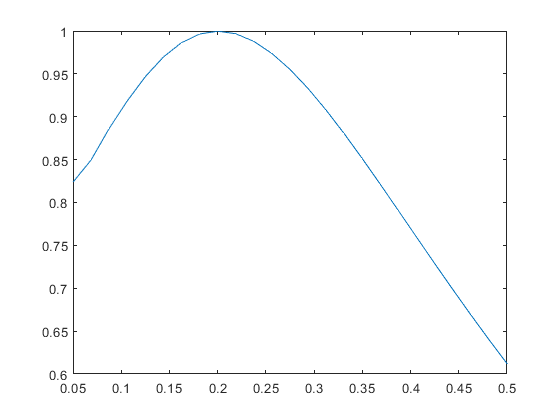

   
plot(dist, abs(ganhos_3d))